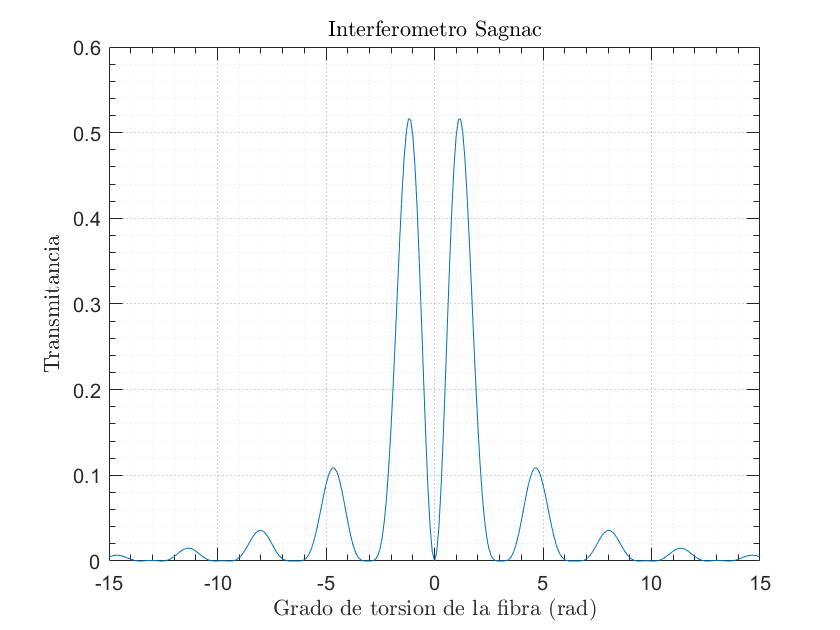

clear
% Ask for input parameters
z = input('Input fiber length');
n = input('Input torsion degree');
x = z / n;

% Determine the number of t-values: from -6 to 6 with step 0.1 yields 121 points.
t_vals = -6:0.1:6;
numSteps = length(t_vals);

Iout = zeros(1, numSteps);
tor = zeros(1, numSteps);

Lam = 1.06e-6;
alf = 0.5;
g = 0.16;

% Generate a random 10-by-n matrix and compute the mean over each column.
k = 4 * rand(10, n);
p = mean(k);    % p is 1-by-n
blj = Lam ./ p;
tet = 0:1:(n-1);   % Angle in degrees

for ind = 1:numSteps
    t = t_vals(ind);
    tor(ind) = t * z;
    Ep = eye(2);
    
    for j = 1:n
        delb = 5.9275e+006 * blj(j);
        S = sqrt((delb/2)^2 + ((2 - g) * t / 2)^2);
        te0 = (tet(j) * pi) / 180;
        A1 = [cos(te0), -sin(te0); sin(te0), cos(te0)];
        G = [cos(S * x) - 1i*(delb/(2*S))*sin(S * x), ((2 - g)*t/(2*S))*sin(S * x); ...
             -((2 - g)*t/(2*S))*sin(S * x), cos(S * x) + 1i*(delb/(2*S))*sin(S * x)];
        Ep = A1 * G * Ep;
    end
    
    B9 = [cos(t * z), -sin(t * z); sin(t * z), cos(t * z)];
    E1 = Ep * B9;
    
    a = E1(1,1);
    b = E1(1,2);
    c = E1(2,1);
    % d = E1(2,2);  % d is defined but not used later
    
    % Multiply the matrix by the vector [1; 0]
    E = [ (2*alf - 1)*a, (1 - alf)*b + alf*c; -alf*b - (1-alf)*c, (1 - 2*alf)*a ] * [1; 0];
    
    % E is a 2x1 vector
    E2x = E(1);
    E2y = E(2);
    Iout(ind) = abs(E2x)^2 + abs(E2y)^2;
end

% Plot the transmitance versus torsion (converted to degrees)
plot(tor, Iout);
title('Interferometro Sagnac',"Interpreter",  "latex")
xlabel("Grado de torsion de la fibra (rad)", "Interpreter",  "latex");
ylabel('Transmitancia',"Interpreter",  "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid


% Find the maximum output and its corresponding torsion value
t1 = tor * 180 / pi;
[Iout_max, elemento] = max(Iout);
raztor_max = t1(elemento);
disp(raztor_max);   % Distance (in degrees) at which maximum propagation occurs

  -68.7549



disp(Iout_max);     % Maximum intensity at the above distance

    0.5164




% Save results to a file (uncomment to save)
out = [t1', Iout'];
% save Trans.dat out -ascii;
